# Objetivo

En esta práctica utilizaremos una red neuronal para clasificar imágenes. Además, utilizaremos el filtro de Gabor y reduciremos las imágenes para detectar mejor las características.

# Prácticas anteriores, qué se necesita

- Gabor kernel Filter (gabor_kernel, gabor_reduce, gabor_template)

- Reduce Image (reduce_image)

- MLP con las funciones necesarias (GetError_class.m, sigmoid.m, sigmoidGradient.m, learningNN_class.m, gradientNN_class.m) u los parámetros (iteraciones, número de neuronas en la capa oculta, alpha)

Esquema general:

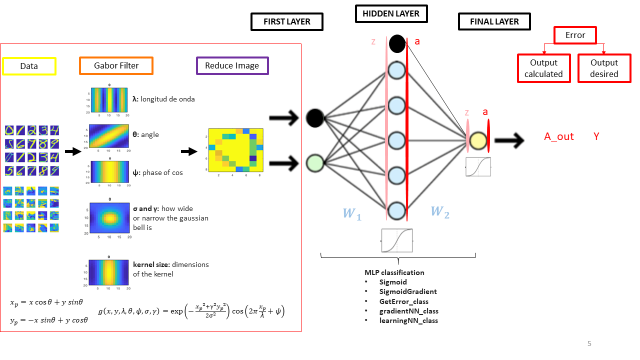

%% load CIFAR dataset 

clear 
clear all


% classes:
% 0:    'avión'
% 1:    'coche'
% 2:    'pájaro'
% 3:    'gato'
% 4:    'ciervo'
% 5:    'perro'
% 6:    'rana'
% 7:    'caballo'
% 8:    'barco'
% 9:    'camión'

%% Elige 2 dígitos entre 0 y 9:
class1 = 2;
name1 = 'Pájaro';
class2 = 0;
name2 = 'Avión';

num_pattern = 300;  % por ejemplo 300, max 10000, si se utilizan todos los patrones, el entrenamiento es muy largo

% NO modificar(esta función separa trainset, data, y testset, data_val) para las 2 clases elegidas
[data,data_val,Ytrain,Yval]=GetDataimages(class1, class2,num_pattern);

% data: datos del conjunto de entrenamiento
% data_val: datos del conjunto de validación
% Ytrain: etiquetas del conjunto de datos de entrenamiento
% Yval: etiquetas del conjunto de datos de validación


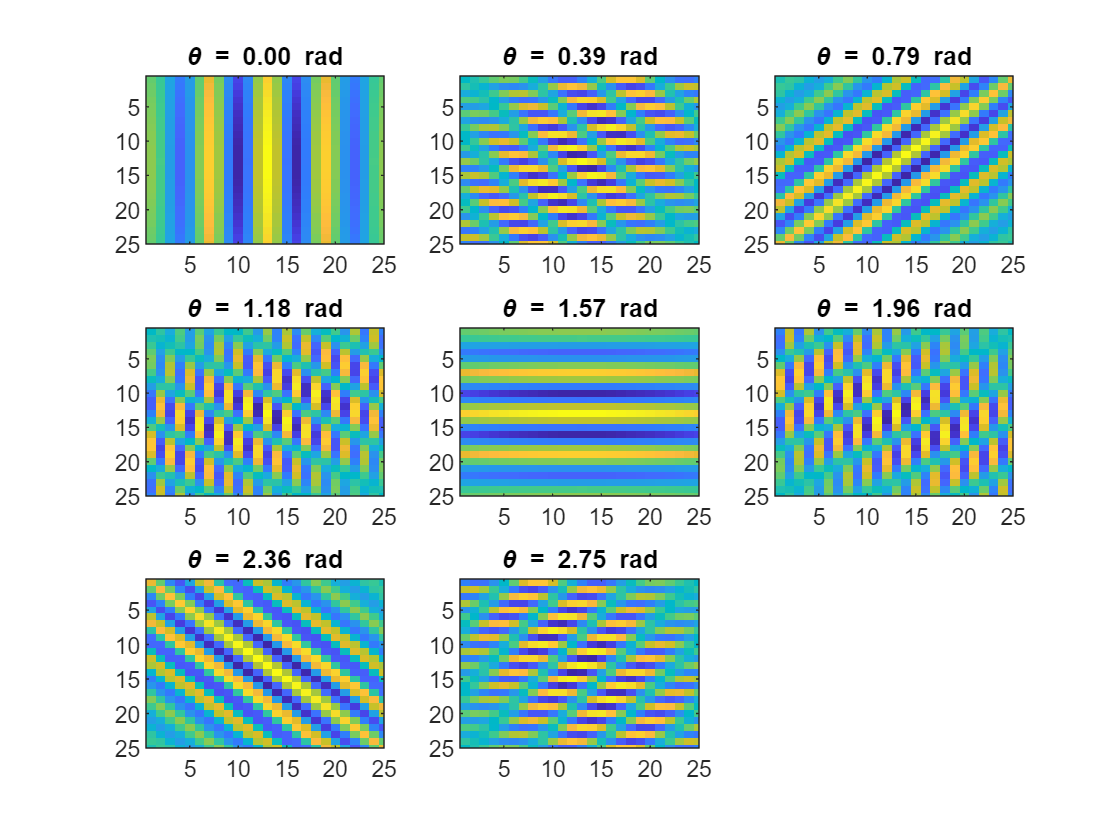

%% Elegir los parámetros de los filtros de Gabor
kern_size = 25;  % Kernel size
lambda = 0.5;     % wavelength (1/frequency)
phi = 0;        % phase offset
sigma = 5;      % Gaussian dispersion
gamma = 0.5;    % height / amplitude ratio

% NO modificar:
fig = false;
orientations = [0*pi/8, 1*pi/8, 2*pi/8, 3*pi/8, 4*pi/8, 5*pi/8, 6*pi/8, 7*pi/8]; %orientaciones de los filtros
image_size = [32 32 3];  %tamaño original de la imagen
reduction_factor = 16;

% Convolución de los datos de entrenamiento:
Xtrain = gabor_reduce(data, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,true);

% Convolución de los datos de validación:
Xval = gabor_reduce(data_val, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,false);

En esta práctica necesitaremos más neuronas en la capa de entrada que en la práctica 3. Asegúrate de que gradientNN_class.m tiene en cuenta esto (W1_grad = d_h*x');

%%  MLP

% Elige los parámetros de la red neuronal:
hidden_units = 80;
max_iter = 100;
alpha = 0.01;

% Gradient Descent: llama a la función de aprendizaje
[E, E_val, W1, W2, ct] = learningNN_class( Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter );

Como en la práctica 3, a continuación evaluamos el clasificador viendo cuántos patrones se clasifican correctamente. La variable **pred** (predicción) valdrá 0 ó 1 dependiendo de si la clase predicha es 1 ó 2. Para ello fijamos los valores de **y** que son iguales a 0 por debajo de 0,5 y los de 1 por encima de 0,5.

%% Predecir la clasificación con datos de entrenamiento

y = zeros(size(Xtrain,2),1);
for p = 1:size(Xtrain,2)  % pattern loop       
    x = Xtrain(:,p); % % entrada de muestra p
    % calcula la activación para las neuronas de la capa oculta:
    z_h = W1 * x;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas de la capa oculta
    a_h = [1; a_h];  % añade el término de sesgo

    % Calcula la activación para la neurona de salida
    z_out = W2 * a_h;  % suma antes de la respuesta de la neurona de salida
    y(p) = sigmoid(z_out);  % calcula la respuesta de la neurona de salida (regression: identity - classification: logistic sigmoid)
end   

pred_t = 0.5 > y;
correct = sum(pred_t == Ytrain) / length(Ytrain);
display(['Porcentaje de clasifiaciones correctas en entrenamiento: ' num2str(correct)])

Porcentaje de clasifiaciones correctas en entrenamiento: 0.48




class1 = sum(Ytrain == 1);
class2 = sum(Ytrain == 0);
cor_class1 = sum(pred_t(Ytrain == 1) == 1) / class1;
cor_class2 = sum(pred_t(Ytrain == 0) == 0) / class2;

%% Predict classification with validation data

yval = zeros(size(Xval,2),1);
for p = 1:size(Xval,2)  % pattern loop       
    x = Xval(:, p); % sample entry for patterns p
     % calculate activation for hidden neurons:
    z_h = W1 * x;  % sum before the sigmoid
    a_h = sigmoid(z_h);  % activation of hidden neurons
    a_h = [1; a_h];  % add the neuron whose value is always equal to one and that serves as bias to the next layer

    % Calculate activation of the output neuron:
    z_out = W2 * a_h;  % sum before the output neuron response function
    yval(p) = sigmoid(z_out);  % calculate output neuron response (regression: identity - classification: logistic sigmoid)  
end    


pred_val = 0.5 > yval;
correct = sum(pred_val == Yval) / length(Yval);
display(['Porcentaje de clasificaciones en validación: ' num2str(correct)])

Porcentaje de clasificaciones en validación: 0.33333





class1_val = sum(Yval == 1);
class2_val = sum(Yval == 0);
cor_class1_val = sum(pred_val(Yval == 1) == 1) / class1_val;
cor_class2_val = sum(pred_val(Yval == 0) == 0) / class2_val;

Visualización de la precisión del MLP para clasificar los datos de entrenamiento y validación:

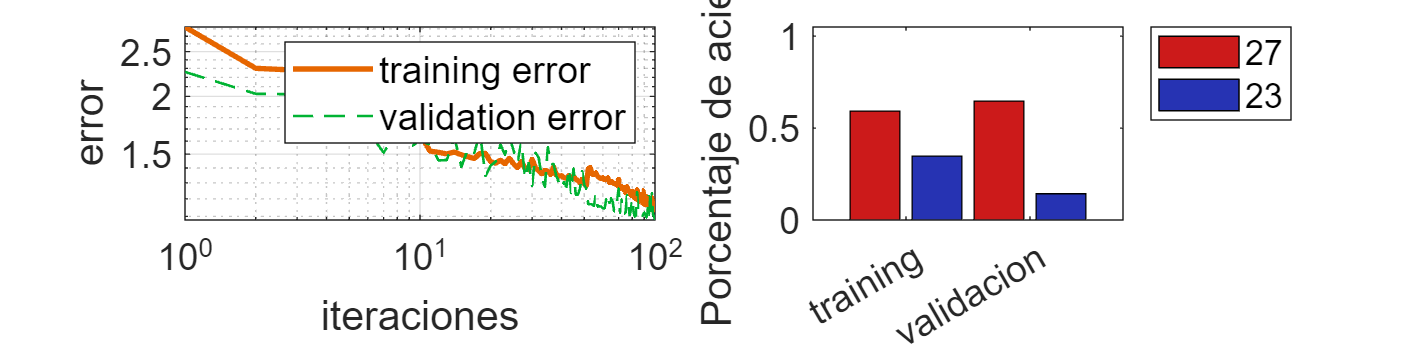

%Gráficas de error y predicciones
figure('NumberTitle', 'off', 'Name', 'Error and Predictions');
set(gcf,'units','normalized','position',[0,0.25,1,0.4])

subplot(121),cla
plot(E, 'color', [.9 .4 0], 'linewidth', 2), hold on
plot(E_val, '--','color', [.0 .7 .2], 'linewidth', 1)
xlabel('iteraciones', 'fontsize', 14)
ylabel('error', 'fontsize', 14)
legend({'training error', 'validation error'}, 'fontsize', 14)
set(gca, 'fontsize', 14,'yscale','log','xscale','log'), grid on

subplot(122),cla
bar(1, cor_class1,'facecolor', [.8 .1 .1])
hold on
bar(2, cor_class2,'facecolor', [.15 .2 .7])
bar(3, cor_class1_val,'facecolor', [.8 .1 .1])
bar(4, cor_class2_val, 'facecolor', [.15 .2 .7])
ylabel('Porcentaje de aciertos', 'fontsize', 14), ylim([0, 1.05])
legend(num2str(class1),num2str(class2),'location','bestoutside'),xlim([0 5])
set(gca, 'fontsize', 14, 'XTick', [1.5,3.5],'XTickLabel',{['training'], 'validacion'} )

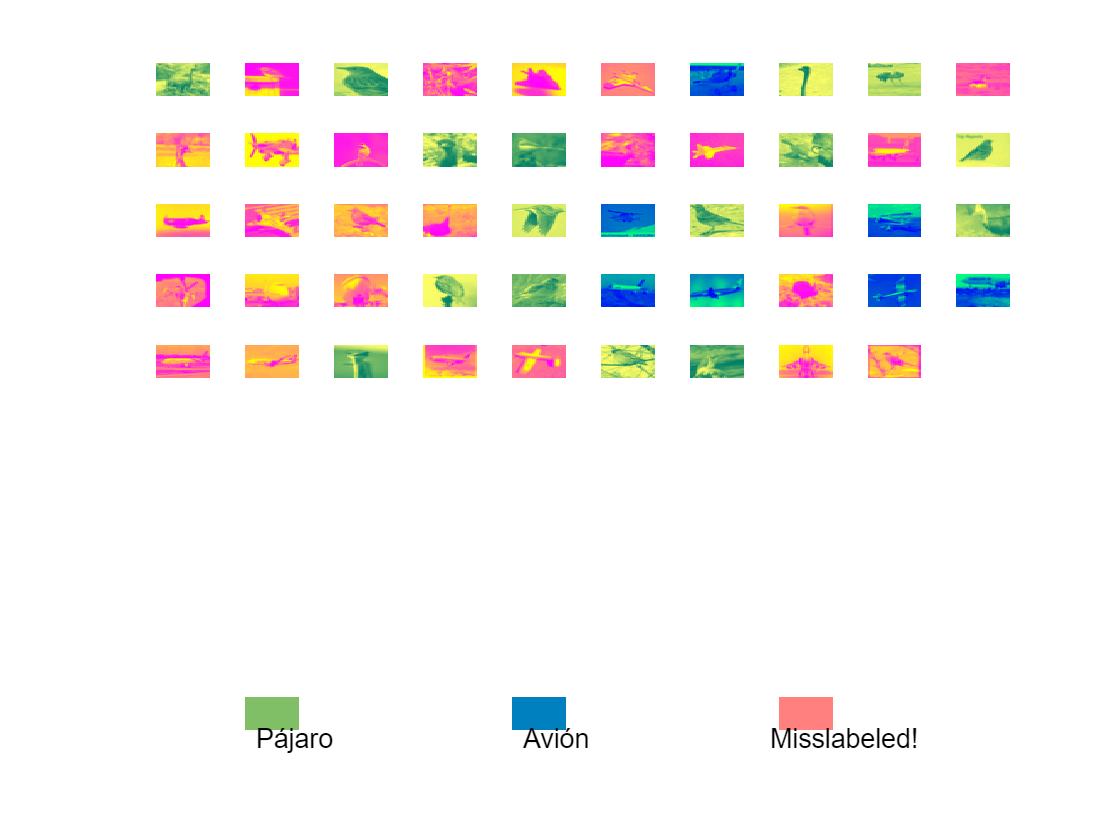

%Plot Predicciones
figure('NumberTitle', 'off', 'Name', 'Training Predictions');
for i = 1:90 % # de ejemplos mostrados
    if i<size(data,1)
   ax1 = subplot(10,10,i);
   img = reshape(data(i,:), image_size);
   img = sum(img, 3);
   img = img';
   imagesc(img);
   axis off
   if pred_t(i) == 1
      colormap(ax1, summer)
   end
   if pred_t(i) == 0
      colormap(ax1, winter)
   end
   if pred_t(i) ~= Ytrain(i)
      colormap(ax1, spring)
   end
    end
end
ax1 = subplot(10,10,92);
imagesc(zeros(32,32));
colormap(ax1, summer)
axis off
text(7 ,40, name1)
ax1 = subplot(10,10,95);
imagesc(zeros(32,32));
colormap(ax1, winter)
axis off
text(7 ,40, name2)
ax1 = subplot(10,10,98);
imagesc(zeros(32,32));
colormap(ax1, spring)
axis off
text(-5 ,40, 'Misslabeled!')

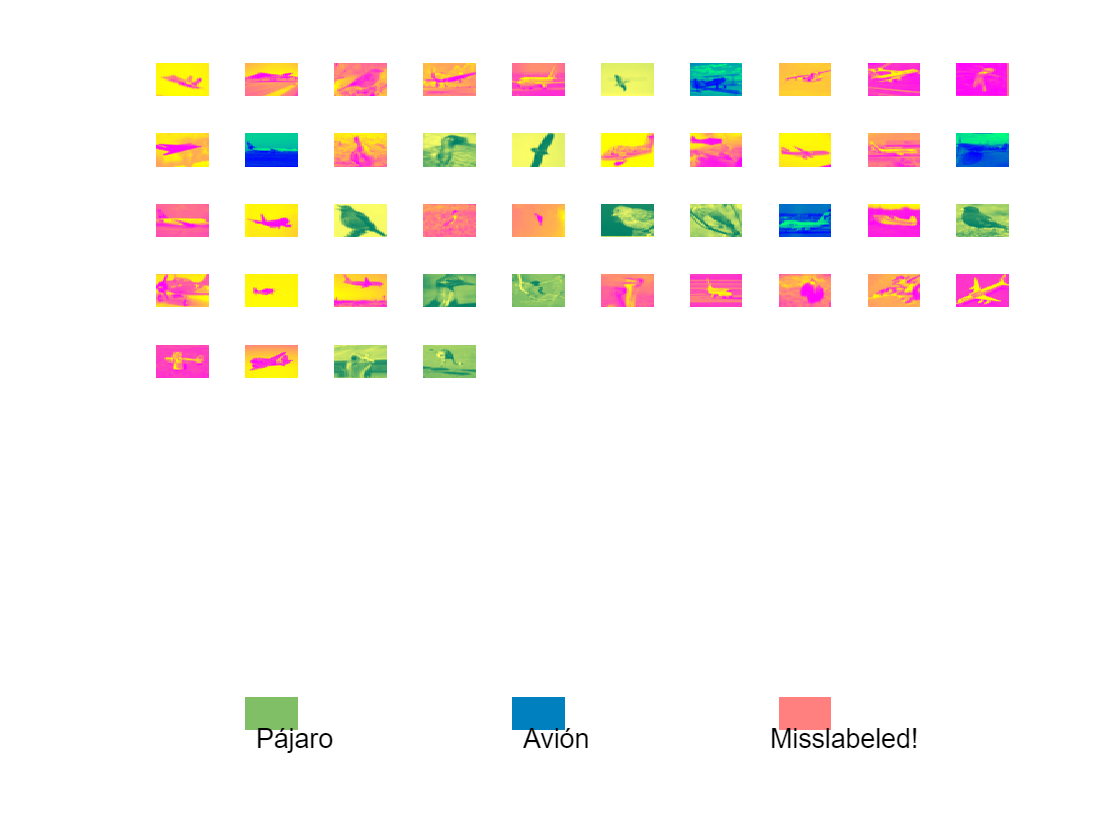


figure('NumberTitle', 'off', 'Name', 'Validation Predictions');
for i = 1:90 %# de ejemplos mostrados
    if i<size(data_val,1)
   ax1 = subplot(10,10,i);
   img = reshape(data_val(i,:), image_size);
   img = sum(img, 3);
   img = img';
   imagesc(img);
   axis off
   if pred_val(i) == 1
      colormap(ax1, summer)
   end
   if pred_val(i) == 0
      colormap(ax1, winter)
   end
   if pred_val(i) ~= Yval(i)
      colormap(ax1, spring)
   end
    end
end
ax1 = subplot(10,10,92);
imagesc(zeros(32,32));
colormap(ax1, summer)
axis off
text(7 ,40, name1)
ax1 = subplot(10,10,95);
imagesc(zeros(32,32));
colormap(ax1, winter)
axis off
text(7 ,40, name2)
ax1 = subplot(10,10,98);
imagesc(zeros(32,32));
colormap(ax1, spring)
axis off
text(-5 ,40, 'Misslabeled!')